# TFM Script

## Introduction

The purpose of this text is to write down the most important ideas and mathematical formulation that is behind the codes implemented for this thesis. As well, the coding process will be also explained. The first purpose of this work is to develop a two degrees of freedom model so that the effect of unsteady aerodynamic drag is analyzed in the classical flutter phenomenon. In order to do so, we will start by studying the typical section of a wing (aerofoil), with two degrees of freedom (pitch and plunge simulating the structural bending and twist of a real three-dimensional wing). 

## 2 DoF Typical Section Model

The first step is to establish the mathematical expression that will determine the motion of the aerofoil when an external load or initial condition is applied. Note that the degrees of freedom are the vertical displacement of the aerofoil $h$ and the pitch $\alpha$. The distance between the elastic axis (which for this model becomes a geometrical point  about which the aerofoil rotates) and the geometrical midpoint of the aerofoil is given by $\textrm{ab}\;$(where $b=\frac{c}{2}$ is the mid chord of the aerofoil). With this geometrical model, the $z$ coordinate of every point of the aerofoil, can be described by $z(x,t) = -h(t) - \alpha(x-ab)$. This allows to derive the vertical velocity $\dot{z}(x,t) = -\dot{h}(t) - \dot{\alpha}(x-ab)$ and therefore the kinetic energy of the aerofoil can be computed as follows: $T = \frac{1}{2}\int \dot{z}^{2}dm$. The potential energy is given by the two springs that model the bending and torsion stiffness of the wing at that specific aerofoil: $U = \frac{1}{2}K_hh^2+\frac{1}{2}K_{\alpha}\alpha^2
$. Applying the Lagrange equation ($\frac{d}{dt} \left(\frac{\partial{T}}{\partial{\dot{q_i}}} \right)+  \frac{\partial{U}}{\partial{q_i}} = Q_{i}^{aero$), we get the two coupled equation of motion that describe the dynamic of the system: 


$$M\ddot{h} + S_{\alpha}\ddot{\alpha} + K_hh = Q_h^{aero}
$$



$$I_{\alpha}\ddot{\alpha} + S_{\alpha}\ddot{h} + K_{\alpha}\alpha = Q_{\alpha}^{aero}$$


Note that no damping terms have been introduced in the previous model. However, in more complex models that are going to be used in the following sections, structural damping (or hysteretic) will be taken into account. The next sections will explain how to obtain the flutter point of the previous dynamic system depending on how the aerodynamic forces are formulated. 

## Quasi-steady Aerodynamic Model

The first model studied is the simplest one, which consists on assuming that the aerodynamic forces act instantaneously with respect to the motion of the aerofoil, and that they only depend on an effective angle of attack, defined as $\alpha_{QS} = \alpha + \frac{\dot{h}}{U_\infty}$. Therefore, the lift provided by the aerofoil will be $L = \frac{1}{2}\rho_\infty U_\infty^2c_{l\alpha}\left(\alpha+\frac{\dot{h}}{U_\infty}\right)c$. From steady thin aerofoil theory, it is known that $c_{l\alpha} = 2\pi

$. Hence, the equations of motion take the following form:


$$M\ddot{h} + S_{\alpha}\ddot{\alpha} + K_hh = -2\pi\rho_\infty U_\infty^2b\left(\alpha+\frac{\dot{h}}{U_\infty}\right)
$$



$$I_{\alpha}\ddot{\alpha} + S_{\alpha}\ddot{h} + K_{\alpha}\alpha = 2\pi\rho_\infty U_\infty^2\left(\alpha+\frac{\dot{h}}{U_\infty}\right)b^2\left(\frac{1}{2}+a\right)
$$


Note that the negative sign in the right hand side of the first equation is due to the fact that the $h
$ degree of freedom is defined with opposite direction with respect to the $z$ coordinate. Also, both right hand sides are multiplied by 2 as $c=2b$. The term $b\left(\frac{1}{2}+a\right)
$ in the pitch motion equation represents the distance between the aerodynamic center (which it assumed to be at $x=-\frac{c}{4}=-\frac{b}{2}$, as the case studied is incompressible flow) and the elastic axis (located at $x=\textrm{ab}$). Then, $x_{EA-AC} = -\frac{b}{2}-ab = -b\left(\frac{1}{2}+a\right)$.

From now on, the previous equations will be properly non dimensionalized. The first equation will be divided by $Mb$ and the second one by $Mb^2$. Introducing the following dimensionless parameters: $r_{\alpha}^2 = \frac{I_{\alpha}}{Mb^2}$, $x_{\alpha} = \frac{S_\alpha}{Mb}$ and taking into account that $K_h = \omega_h^2M
$and $K_\alpha = \omega_\alpha^2 I_\alpha
$, we get:


$$\frac{\ddot{h}}{b} + x_{\alpha}\ddot{\alpha} + \omega_h^2\frac{h}{b} = -\frac{2\pi\rho_\infty U_\infty^2}{M}\left(\alpha+\frac{\dot{h}}{U_\infty}\right)$$



$$r_{\alpha}^2\ddot{\alpha} + x_{\alpha}\frac{\ddot{h}}{b} + \omega_{\alpha}^2\alpha = \frac{2\pi\rho_\infty U_\infty^2}{M}\left(\alpha+\frac{\dot{h}}{U_\infty}\right)\left(\frac{1}{2}+a\right)
$$


Note that $\omega_h$ and $\omega_\alpha$ are the natural frequencies of oscillation of the structural modes of the aerofoil (bending and torsion).

clear all;
close all;
clc;

%% Parameters definition

rho_inf = 1.225;
mu = 20;
b = 1;
M = mu*pi*rho_inf*b^2;
a = -0.25;
r_alpha = 0.5;
omega_alpha = 8*pi;
omega_h = 4*pi;
x_alpha = 0.1;

The next step is to transform the equations to the Laplace domain, so that the stability of the system can be analyzed depending on the values of the parameters. Then, the degrees of freedom of the problem can be expressed as $h = \bar{h}e^{pt}
$ and $\alpha = \bar{\alpha}e^{pt}$, where $\bar{h}
$ and $\bar{\alpha}

$ are complex numbers due to the time phase between the plunge and pitch motions of the aerofoil. The Laplace variable $p=\sigma +i\omega$ contains the damping of the system in its real part, and the frequency of oscillation in the imaginary part. Notice that $p$ contains the information which establish if the system is stable or unstable, as if for at least one mode of oscillation $\sigma >0$, the system will diverge and therefore the system  will be unstable. If we introduce the Laplace variable, the equations of motion can be written as:


$$p^2\frac{\bar{h}}{b} + p^2x_{\alpha}\bar{\alpha} + \omega_h^2\frac{\bar{h}}{b} = -\frac{2\pi\rho_\infty U_\infty^2}{M}\left(\bar{\alpha}+p\frac{\bar{h}}{U_\infty}\right)$$



$$p^2r_{\alpha}^2\bar{\alpha} + p^2x_{\alpha}\frac{\bar{h}}{b} + \omega_{\alpha}^2\bar{\alpha} = \frac{2\pi\rho_\infty U_\infty^2}{M}\left(\bar{\alpha}+p\frac{\bar{h}}{U_\infty}\right)\left(\frac{1}{2}+a\right)$$


In matrix format, the system of equations can be expressed as:


$$\left(p^2\left[\matrix{1 & x_\alpha \cr  x_\alpha & r_\alpha^2}\right] + \left[\matrix{\omega_h^2 & 0 \cr  0 & r_\alpha^2\omega_\alpha^2}\right] \right)\left\{\matrix{\frac{\bar h}{b} \cr \bar\alpha}\right\} = \frac{2\pi\rho_\infty U_\infty^2}{M}\left[\matrix{-\frac{b}{U_\infty}p & -1 \cr  \frac{b}{U_\infty}\left(\frac{1}{2}+a\right)p & \left(\frac{1}{2}+a\right)}\right]\left\{\matrix{\frac{\bar h}{b} \cr \bar\alpha}\right\} $$


Reorganizing all the terms in the a unique matrix, we get


$$\left[\matrix{p^2+\omega_h^2+\frac{2\pi\rho_\infty U_\infty b}{M}p& x_\alpha p^2+\frac{2\pi \rho_\infty U_\infty^2}{M} \cr  x_\alpha p^2-\frac{2\pi \rho_\infty U_\infty b}{M}\left(\frac{1}{2}+a\right)p & r_\alpha^2\left(p^2+\omega_\alpha^2\right)-\frac{2\pi \rho_\infty U_\infty^2}{M}\left(\frac{1}{2}+a\right)}\right]\left\{\matrix{\frac{\bar h}{b} \cr \bar\alpha}\right\}  = \left\{\matrix{0 \cr 0 }\right\}$$


Apart from the trivial solution, the way of ensuring that the matrix equation is satisfied is by enforcing the determinant of the matrix to be zero. Consequently, de equation that provides the solution of the two modes of the system is $\det \left(A\right)=0\ldotp$ Being $A$ the matrix previously determined. This gives a characteristic polynomial as follows:

$A_4p^4+A_3p^3+A_2p^2+A_1p+A_0 = 0$.

The solutions of the system for each mode in the Laplace domain, are calculated by computing the values of $p$ for range of flow velocities $U_\infty
$ that comply with the characteristic polynomial of the system. Recall that once $p$ is calculated, the damping coefficient of the system is obtained from the real part of the solution and the frequency from the imaginary.

N_iter = 1000; 
U_min = 0;
U_max = 100;
U_range = linspace(U_min,U_max,N_iter);
Damping_11 = zeros(N_iter,1);
Damping_12 = zeros(N_iter,1);
Damping_21 = zeros(N_iter,1);
Damping_22 = zeros(N_iter,1);
Freq_11 = zeros(N_iter,1);
Freq_12 = zeros(N_iter,1);
Freq_21 = zeros(N_iter,1);
Freq_22 = zeros(N_iter,1);
p_11 = zeros(N_iter,1);
p_12 = zeros(N_iter,1);
p_21 = zeros(N_iter,1);
p_22 = zeros(N_iter,1);

for i = 1:N_iter

    U_inf = U_range(i);
    A4 = r_alpha^2 - x_alpha^2;
    A3 = 2*pi*rho_inf*U_inf*b/M * (r_alpha^2 + x_alpha*(0.5+a));
    A2 = omega_alpha^2*r_alpha^2 + omega_h^2*r_alpha^2 - 2*pi*rho_inf*U_inf^2*(0.5+a)/M - 2*pi*x_alpha*rho_inf*U_inf^2/M;
    A1 = 2*pi*rho_inf*U_inf*b/M*(omega_alpha^2*r_alpha^2 - 2*pi*rho_inf*U_inf^2*(0.5+a)/M) + (2*pi*rho_inf/M)^2*b*U_inf^3*(0.5+a);
    A0 = omega_h^2*omega_alpha^2*r_alpha^2 - 2*pi*omega_h^2*rho_inf*U_inf^2*(0.5+a)/M;
    Characteristic_Polynomial = [A4 A3 A2 A1 A0];
    p = roots(Characteristic_Polynomial);
    p_11(i) = p(1);
    p_12(i) = p(2);
    p_21(i) = p(3);
    p_22(i) = p(4);
    Damping_11(i) = real(p_11(i));
    Damping_12(i) = real(p_12(i));
    Damping_21(i) = real(p_21(i));
    Damping_22(i) = real(p_22(i)); 
    Freq_11(i) = imag(p_11(i));
    Freq_12(i) = imag(p_12(i));
    Freq_21(i) = imag(p_21(i));
    Freq_22(i) = imag(p_22(i));
end

In order to obtain the flutter point, we seek for the stability limit in which $\sigma = 0$. As we are covering a finite number of flow velocities, most probably what will happen is that non of them coincide exactly with the flutter point. Therefore, a linear interpolation between the two points of the solution where $\sigma
$ changes sign is carried out. The algorithm applied works as follows: Imagine that the change in sign of $\sigma$ occurs between point $\sigma_n$ and $\sigma_{n+1}$. In that points, the velocities are $U_{\infty,n}
$ and $U_{\infty,n+1}$. Then, with a linear interpolation we have $U_{Flutter} =U_{\infty,n}+ \frac{U_{\infty,n+1}-U_{\infty,n}}{\sigma_{n+1}-\sigma_{n}}\left (0-\sigma_n\right)$. Same process is applied in order to get the flutter frequency of oscillation. Notice that the code is implemented so that the flutter is calculated for the mode in which the change in sign occurs for lower airspeed. 

%% Flutter point 

idx_mode1 = find(Damping_11(2:end-1).*Damping_11(3:end) < 0);
idx_mode2 = find(Damping_21(2:end-1).*Damping_21(3:end) < 0);

if isempty(idx_mode1) && isempty(idx_mode2)

   disp('No flutter point in the reduced frequency range studied. Change k_range or problem parameters');

elseif isempty(idx_mode2)

    idx_flutter_mode1 = idx_mode1(length(idx_mode1));
    idx_flutter = idx_flutter_mode1;
    U_flutter = U_range(idx_flutter) + ((U_range(idx_flutter+1) - U_range(idx_flutter))/...
        (Damping_11(idx_flutter+1) - Damping_11(idx_flutter)))*(-Damping_11(idx_flutter));
    Freq_flutter = (Freq_11(idx_flutter) + ((Freq_11(idx_flutter+1) - Freq_11(idx_flutter))/...
        (Damping_11(idx_flutter+1) - Damping_11(idx_flutter)))*(-Damping_11(idx_flutter)))/(2*pi);

elseif isempty(idx_mode1)

    idx_flutter_mode2 = idx_mode2(length(idx_mode2));
    idx_flutter = idx_flutter_mode2;
    U_flutter = U_range(idx_flutter) + ((U_range(idx_flutter+1) - U_range(idx_flutter))/...
        (Damping_21(idx_flutter+1) - Damping_21(idx_flutter)))*(-Damping_21(idx_flutter));
    Freq_flutter = (Freq_21(idx_flutter) + ((Freq_21(idx_flutter+1) - Freq_21(idx_flutter))/...
        (Damping_21(idx_flutter+1) - Damping_21(idx_flutter)))*(-Damping_21(idx_flutter)))/(2*pi);
else

    [idx_flutter, mode] = min([idx_mode1 ;idx_mode2]);
    
    if mode == 1
        U_flutter = U_range(idx_flutter) + ((U_range(idx_flutter+1) - U_range(idx_flutter))/...
            (Damping_11(idx_flutter+1) - Damping_11(idx_flutter)))*(-Damping_11(idx_flutter));
        Freq_flutter = (Freq_11(idx_flutter) + ((Freq_11(idx_flutter+1) - Freq_11(idx_flutter))/...
            (Damping_11(idx_flutter+1) - Damping_11(idx_flutter)))*(-Damping_11(idx_flutter)))/(2*pi);
    else
        U_flutter = U_range(idx_flutter) + ((U_range(idx_flutter+1) - U_range(idx_flutter))/...
            (Damping_21(idx_flutter+1) - Damping_21(idx_flutter)))*(-Damping_21(idx_flutter));
        Freq_flutter = (omega_mode(idx_flutter) + ((omega_mode(idx_flutter+1) - omega_mode(idx_flutter))/...
            (Damping_21(idx_flutter+1) - Damping_21(idx_flutter)))*(-Damping_21(idx_flutter)))/(2*pi);
    end

end


The following part of the code allows to plot the frequencies and damping coefficient of both modes as a function of the flow speed

%% Vg and Vf plots

zero_damping = 0:0.1:100;

figure(1)

plot(U_range,Freq_11/(2*pi),'Blue')
hold on
plot(U_range, Freq_21/(2*pi),'Red')
hold on
xline(U_flutter, 'k--', 'LineWidth',1.2);
hold on
yline(Freq_flutter, 'k--', 'LineWidth',1.2);
hold on 
plot(U_flutter, Freq_flutter, 'md', 'MarkerSize',7, 'MarkerFaceColor','m')
xlabel('$U_{\infty}\mathrm{[m/s]}$','interpreter','latex')
ylabel('$f\mathrm{[Hz]}$','interpreter','latex')
xlim([0 U_flutter+2])
%ylim([0.4 2])
grid on
grid minor 
box on
set(gcf, 'Units', 'inches', 'Position', [0, 0, 6, 4]);
set(gca, 'FontSize', 10, 'FontName', 'Times New Roman')

figure(2)

plot(U_range, Damping_11,'Blue')
hold on
plot(U_range, Damping_21,'Red')
hold on
yline(0, 'k-', 'LineWidth',0.5);
hold on
xline(U_flutter, 'k--', 'LineWidth',1.2);
hold on
plot(U_flutter, 0, 'md', 'MarkerSize',7, 'MarkerFaceColor','m')
xlabel('$U_{\infty}\mathrm{[m/s]}$','interpreter','latex')
ylabel('$\sigma\mathrm{[-]}$','interpreter','latex')
xlim([0 U_flutter+2])
%ylim([-0.2 0.2])
grid on
grid minor
box on
set(gcf, 'Units', 'inches', 'Position', [0, 0, 6, 4]);
set(gca, 'FontSize', 10, 'FontName', 'Times New Roman')

## k-Method with Theodorsen's Aerodynamic Model

The next step is solving the flutter problem but taking into account the complete unsteady aerodynamic model that results from Theodorsen's formulation of the unsteady aerodynamic forces for harmonic motion of the aerofoil. It has been taken into account that this model is developed for a pitch and plunge case, plus the possibility of having a control surface that rotates about the hinge line. In this case, the model studied has only the degrees of freedom corresponding to plunge and pitch so the control surface terms are neglected. Following Bisplinghoff, the unsteady aerodynamic forces can be expressed as:


$$\frac{\bar{Q}_h(k)}{q_\infty b} = -2\pi\left[\frac{b}{U_\infty}\dot{\alpha} + \left(\frac{b}{U_\infty}\right)^2\left(\frac{\ddot{h}}{b} - a\ddot\alpha\right)\right]-4\pi C(k)\left\{\alpha+\frac{b}{U_\infty}\left[\frac{\dot{h}}{b}+\left(\frac{1}{2}-a\right)\dot{\alpha}\right]\right\}$$



$$\frac{\bar{Q}_\alpha(k)}{q_\infty b^2} = -2\pi\left\{\frac{b}{U_\infty}\left(\frac{1}{2}-a\right)\dot{\alpha} + \left(\frac{b}{U_\infty}\right)^2\left[-a\frac{\ddot{h}}{b} + \left(\frac{1}{8}+a^2\right)\ddot\alpha\right]\right\} + 4\pi \left(\frac{1}{2}+a\right) C(k)\left\{\alpha+\frac{b}{U_\infty}\left[\frac{\dot{h}}{b}+\left(\frac{1}{2}-a\right)\dot{\alpha}\right]\right\}$$


Where $C\left(k\right)$is the Theodorsen's function (defined later in this section). It is important to take into account that although the formulation uses the time derivatives of the two degrees of freedom, it is only valid for harmonic motion of the aerofoil.

As is going to be explained now, the k-method solves the system assuming harmonic oscillations of the degrees of freedom. Therefore, we can introduce hysteretic or structural damping to the system. Then, the system of equations results as:


$$M\ddot{h} + S_{\alpha}\ddot{\alpha} +K_hg_h\frac{1}{\omega}\dot{h}+K_hh = Q_h^{aero}(k)
$$



$$I_{\alpha}\ddot{\alpha} + S_{\alpha}\ddot{h} + \frac{1}{\omega}K_\alpha g_\alpha \dot{\alpha}+  K_{\alpha}\alpha = Q_\alpha^{aero}(k)$$


Applying the same dimensionless variables as for the quasi-steady case previously explained, the equations become:


$$\frac{\ddot{h}}{b} + x_{\alpha}\ddot{\alpha} + \frac{1}{\omega}g_h\omega_h^2\frac{\dot h}{b} + \omega_h^2\frac{h}{b} = \frac{Q_h^{aero}(k)}{Mb}$$



$$r_\alpha^2\ddot{\alpha} + x_{\alpha}\frac{\ddot{h}}{b} + \frac{1}{\omega}g_\alpha\omega_\alpha^2\dot \alpha+  \omega_\alpha^2\alpha = \frac{Q_\alpha^{aero}(k)}{Mb^2}$$


An now if we apply the condition of harmonic motion ($h=\bar{h} e^{i\omega t}$ and $\alpha =\bar{\alpha} e^{i\omega t}$), we get


$$-\omega^2\frac{\bar{h}}{b} - \omega^2x_{\alpha}\bar{\alpha} + \omega_h^2(1+ig_h)\frac{\bar{h}}{b} = \frac{\bar Q_h^{aero}(k)}{Mb}$$



$$-\omega^2r_{\alpha}^2\bar{\alpha} - \omega^2x_{\alpha}\frac{\bar{h}}{b} + \omega_{\alpha}^2(1+ig_\alpha)\bar{\alpha} = \frac{\bar Q_\alpha^{aero}(k)}{Mb^2}$$


Below you can find the first lines of the code just to declare the parameters that are needed to compute this flutter method.

%% "k" method (also call Vg-Vf) for Classical flutter

%% Parameters of the problem definition

rho_inf = 1.225; % Airflow density, depends on the altitude studied
b = 1; % Semi-chord
a = -0.2; % Dimensionless distance from the Elastic Axis to the geometrical half point of the airfoil
r_alpha = sqrt(6/25); % Dimensionless radius of the airfoil
omega_alpha = 5*pi; % Uncoupled natural frequency of torsion mode
omega_h = 2*pi; % Uncoupled natural frequency of bending mode
x_alpha = 0.1; % Dimensionless distance from the CG to the geometrical half point of the airfoil: x_alpha = e - a (in Hodges biblio.)
g_alpha = 0.0; % Damping coefficient of the structure
mu = 20; % Masic parameter mu = M/(pi*rho_inf*b^2)
mass = mu*pi*rho_inf*b^2; % Mass of the airfoil (per unit of semi-span)
n_DoF = 2; % Number of degrees of freedom of the system, and thus number of aeroelastic modes considered


Regarding the unsteady aerodynamic forces, if we apply the harmonic motion assumption to the Theodorsen model we get


$$\frac{\bar{Q}_h(k)}{q_\infty b} = -2\pi\left[\frac{b}{U_\infty}i\omega\bar{\alpha} + \left(\frac{b}{U_\infty}\right)^2\left(-\omega^2\frac{\bar{h}}{b} + a\omega^2\bar\alpha\right)\right]-4\pi C(k)\left\{\bar\alpha+\frac{b}{U_\infty}\left[i\omega\frac{\bar{h}}{b}+\left(\frac{1}{2}-a\right)i\omega\bar{\alpha}\right]\right\}$$



$$\frac{\bar{Q}_\alpha(k)}{q_\infty b^2} = -2\pi\left\{\frac{b}{U_\infty}\left(\frac{1}{2}-a\right)i\omega\bar{\alpha} + \left(\frac{b}{U_\infty}\right)^2\left[a\omega^2\frac{\bar{h}}{b} + -\omega^2\left(\frac{1}{8}+a^2\right)\bar\alpha\right]\right\} + 4\pi \left(\frac{1}{2}+a\right) C(k)\left\{\bar\alpha+\frac{b}{U_\infty}\left[\frac{i\omega\bar{h}}{b}+\left(\frac{1}{2}-a\right)i\omega\bar{\alpha}\right]\right\}$$


Introducing the dimensionless parameter called reduced frequency $k=\frac{\omega b}{U_{\infty } }$ the previous equations result in:


$$\frac{\bar{Q}_h(k)}{q_\infty b} = -2\pi\left(ik\bar{\alpha} + -k^2\frac{\bar{h}}{b} + ak^2\bar\alpha\right)-4\pi C(k)\left[\bar\alpha+ik\frac{\bar{h}}{b}+\left(\frac{1}{2}-a\right)ik\bar{\alpha}\right]\$$



$$\frac{\bar{Q}_\alpha(k)}{q_\infty b^2} = -2\pi\left[\left(\frac{1}{2}-a\right)ik\bar{\alpha} + ak^2\frac{\bar{h}}{b} -k^2\left(\frac{1}{8}+a^2\right)\bar\alpha\right] + 4\pi \left(\frac{1}{2}+a\right) C(k)\left[\bar\alpha+ik\frac{\bar{h}}{b}+\left(\frac{1}{2}-a\right)ik\bar{\alpha}\right]$$


In order to reorganize the equations in matrix format, we can define a matrix of aerodynamic coefficients such

    
$$\left[\matrix{ \bar C_{hh} & \bar C_{h\alpha} \cr \bar C_{mh} & \bar C_{m\alpha}}\right]\left\{\matrix{\frac{\bar h}{b} \cr \bar\alpha}\right\} = \left\{\matrix{\frac{\bar{Q}_h(k)}{q_\infty b}  \cr \frac{\bar{Q}_\alpha(k)}{q_\infty b^2} }\right\}$$


where the coefficients are


$$\bar C_{hh} = -2\pi\left[-k^2+2ikC(k)\right]$$



$$\bar C_{h\alpha} = -2\pi\left\{ak^2+ik+2C(k)\left[1+\left(\frac{1}{2}-a\right)ik\right]\right\}$$



$$\bar C_{mh} = 2\pi\left[-ak^2 + 2ikC(k)\left(\frac{1}{2}+a\right)\right]$$



$$\bar C_{m\alpha} = 2\pi \left\{-ik\left(\frac{1}{2}-a\right) + \left(\frac{1}{8}+a^2\right)k^2+2C(k)\left(\frac{1}{2}+a\right)\left[1+ik\left(\frac{1}{2}-a\right)\right]\right\}$$


Note that below we find the functions used to compute the aerodynamic coefficient matrix. The Theodorsen's function is computed as a function of the first and second order Bessel function, that are available in Matlab.

%% Unsteady aerodynamic functions

function Q_aero = Unsteady_aero(k,a)
    
    C = Theodorsen_function(k);
    Q_aero = zeros(2,2);
    Q_aero(1,1) = -2*pi*(-k^2 + 2*1i*k*C);
    Q_aero(1,2) = -2*pi*(a*k^2 + 1i*k + 2*C*(1 + (0.5-a)*1i*k));
    Q_aero(2,1) = 2*pi*(-a*k^2 + 2*1i*k*C*(0.5+a));
    Q_aero(2,2)= 2*pi*(-1i*k*(0.5-a) + k^2*(1/8+a^2) + 2*C*(0.5+a)*(1 + (0.5-a)*1i*k));

end

function C = Theodorsen_function(k)
    
    C = besselh(1,2,k)/(besselh(1,2,k) + 1i*besselh(0,2,k));

end

If we now organize the left hand side (structural part) in matrix format we have:


$$\left(-\omega^2\left[\matrix{1 & x_\alpha \cr  x_\alpha & r_\alpha^2}\right] + \left(1+ig_\alpha\right)\left[\matrix{\omega_h^2 & 0 \cr  0 & r_\alpha^2\omega_\alpha^2}\right] \right)\left\{\matrix{\frac{\bar h}{b} \cr \bar\alpha}\right\} $$


Where it has been assumed that $g_h = g_\alpha$, which is a required assumption carried out for k-Method to be formulated as an eigenvalue-eigenvector problem, as it will be seen later. In bibliography as Demasi's book, it is said that in reality, the estimation of these structural damping coefficients is not sufficiently precise to get the exact values, but usually both modes have very similar coefficients. Therefore, the assumption is valid and mathematically convenient for the method formulation. Moreover, after running the code it is probed that this values change very little the flutter point, as the aerodynamic damping is some orders of magnitude larger than the structural one (for a large airspeed range).

The next step is to non dimensionalize the left and right hand sides of the equations with the same parameters. Regarding the left hand side (inertial and structural terms), we still have to divide by $\omega^2
$ to completely get a dimensionless system of equations. Therefore we get 


$$\left(-\left[\matrix{1 & x_\alpha \cr  x_\alpha & r_\alpha^2}\right] + \left(\frac{\omega_\alpha}{\omega}\right)^2\left(1+ig_\alpha\right)\left[\matrix{\left(\frac{\omega_h}{\omega_\alpha}\right)^2 & 0 \cr  0 & r_\alpha^2}\right] \right)\left\{\matrix{\frac{\bar h}{b} \cr \bar\alpha}\right\} $$


The definition of this matrices in the code is the following:

%% Definition of non dimensionalized mass and stiffness matrices

M = [1 x_alpha; x_alpha r_alpha^2];
K = [(omega_h/omega_alpha)^2 0; 0 r_alpha^2];

As it was presented previously, the aerodynamic coefficients matrix give the aerodynamic forces divided by $q_\infty b$ and $q_\infty b^2$. But the left hand side is non dimensionalize with $M\omega^2b$ and $M\omega^2 b^2$respectively. Then, we need to get the expression of the aerodynamic forces divided by the same parameters than the structural and inertia terms. If we introduce a new non dimensional parameter $\mu =\frac{M}{\pi \rho_{\infty } b^2 }$, called mass parameter (relates the mass of the aerofoil with the mass corresponding to a circle of air of radius $b$), we can get the following relation:


$$\frac{1}{M\omega^2 b} = \frac{1}{q_\infty b}\frac{q_\infty}{M\omega^2} = \frac{1}{q_\infty b}\frac{\rho_\infty U_\infty^2}{2M\omega^2} = \frac{1}{q_\infty b}\frac{\pi\rho_\infty b^2}{M} \frac{1}{2\pi} \frac{U_\infty^2}{\omega^2b^2} =  \frac{1}{q_\infty b}\frac{1}{2\pi\mu k^2}$$


Therefore, we have that 


$$\left(-\left[\matrix{1 & x_\alpha \cr  x_\alpha & r_\alpha^2}\right] + \left(\frac{\omega_\alpha}{\omega}\right)^2\left(1+ig_\alpha\right)\left[\matrix{\left(\frac{\omega_h}{\omega_\alpha}\right)^2 & 0 \cr  0 & r_\alpha^2}\right] \right)\left\{\matrix{\frac{\bar h}{b} \cr \bar\alpha}\right\} = \frac{1}{2\pi\mu k^2}\left\{\matrix{\frac{\bar{Q}_h(k)}{q_\infty b}  \cr \frac{\bar{Q}_\alpha(k)}{q_\infty b^2} }\right\} = \frac{1}{2\pi\mu k^2} \left[\matrix{ \bar C_{hh} & \bar C_{h\alpha} \cr \bar C_{mh} & \bar C_{m\alpha}}\right]\left\{\matrix{\frac{\bar h}{b} \cr \bar\alpha}\right\} $$


Reorganizing all the terms in the left hand side, we get


$$\left(-\left[\matrix{1 & x_\alpha \cr  x_\alpha & r_\alpha^2}\right] + \left(\frac{\omega_\alpha}{\omega}\right)^2\left(1+ig_\alpha\right)\left[\matrix{\left(\frac{\omega_h}{\omega_\alpha}\right)^2 & 0 \cr  0 & r_\alpha^2}\right] - \frac{1}{2\pi\mu k^2} \left[\matrix{ \bar C_{hh} & \bar C_{h\alpha} \cr \bar C_{mh} & \bar C_{m\alpha}}\right]\right)\left\{\matrix{\frac{\bar h}{b} \cr \bar\alpha}\right\}  =  \left\{\matrix{0 \cr 0 }\right\}$$


In order to simplify the notation now on, we are going to call $[M]$ to the inertia matrix, $[K]$ to the structural stiffness matrix, and $[C_{aero}]$ to the aerodynamic coefficients matrix, so that we have 


$$\left(-[M]+\left(\frac{\omega_\alpha}{\omega}\right)^2\left(1+ig_\alpha\right)[K]-\frac{1}{2\pi\mu k^2}[C_{aero}]\right)\left\{\bar q\right\} = \left\{\bar 0 \right\}$$


If we multiply the equation by the inverse of the stiffness matrix ${\left\lbrack K\right\rbrack }^{-1}$ and by $-1$ we get 


$$\left\{[K]^{-1}\left([M] + \frac{1}{2\pi\mu k^2}[C_{aero}]\right) -\left(\frac{\omega_\alpha}{\omega}\right)^2\left(1+ig_\alpha\right)[I] \right\} \left\{\bar q \right\}= \left\{\bar 0 \right\}$$


This last equation is an eigenvalue-eigenvector linear algebraic problem in the form $\left([A]-\lambda[I]\right)\left\{\bar q \right\} = \left\{\bar0\right\}$, where 

$[A] = [K]^{-1}\left([M] + \frac{1}{2\pi\mu k^2}[C_{aero}]\right)$ and $\lambda = \left(\frac{\omega_\alpha}{\omega}\right)^2\left(1+ig_\alpha\right)$.

Hence, we deduce that the flutter point can be studied by computing the eigenvalues of matrix $\left\lbrack A\right\rbrack$. One of the important issues to point out here is that the matrix $[A]
$, as well as the matrix of aerodynamic coefficients $\left\lbrack C_{\textrm{aero}} \right\rbrack$, depend on the reduced frequency $k$, which is an unknown of the system. Thus, the only way in which we can get the flutter point is by iterating for different values of the reduced frequency. Before explaining how we can get the flutter point through this iterative process, it is important to understand one of the keys of the k-method, which was introduced at the very beginning of the explanation of the method. This "trick" was to assume that every degree of freedom of the system has harmonic oscillations. This assumption is of great importance, as it is only physically true when the system is exactly at the flutter point, since otherwise, the system will either damp the oscillations or diverge dynamically and therefore the assumption will not be fulfill. Thus, the results obtained by the k-method are not truly reliable at any point different from the flutter point as the Theodorsen's unsteady aerodynamic model only predicts the loads produced by the aerofoil when it is under harmonic motion, and not in any different condition. 

In order to compute the flutter point of the aeroelastic system, we have to fix the value of the reduced frequency $k$ and solve for the eigenvalues of the system. It is important to point out that with the k method, we are not fixing the values of the flow velocity $U_{\infty }$ at any point, so it will be recovered as part of the solution. At this point it is of paramount important to understand how to decide if the system is stable, marginally stable, or unstable, depending on the eigenvalues computed. As it was justified earlier, the eigenvalues have the following structure: 


$$\lambda = \left(\frac{\omega_\alpha}{\omega}\right)^2\left(1+ig_\alpha\right)$$


As it can be seen, the frequency of oscillation of each aeroelastic mode can be obtained as $\omega = \frac{\omega_\alpha}{\sqrt{Re\left(\lambda\right)}$. And therefore, the flow velocity can be calculated as $U_{\infty } =\frac{\omega b}{k}$. In addition, we can get the damping of each aeroelastic mode as $g_\alpha = \frac{Im\left(\lambda\right)}{Re\left(\lambda\right)}$. Here is where it comes the key point. We are obtaining the damping of the system $g_{\alpha }$ as part of the solution itself and not by imposing the value of this parameter in any term of the system's equations. This will result in obtaining values of $g_{\alpha }$ different than the one known for the aerofoil structural damping which is being studied. Apparently, this make no sense, but it is actually the way that the k-method has to evaluate the stability of the system. We have turned the structural damping of the system $g_{\alpha }$ in a degree of freedom, in order to be able to assume that the system is always oscillating harmonically. Then, let me rename the damping obtained as an eigenvalue solution as $g
$, so that $\lambda = \left(\frac{\omega_\alpha}{\omega}\right)^2\left(1+ig\right)$. Hence, $g
$ can be interpreted as the value of the structural damping coefficient that the system should has to present harmonic motion (which is assumed for this k-method solution). This way, we can classify the stability of each aeroelastic mode as follows:

If $g<g_\alpha
$, the aeroelastic mode is presenting harmonic oscillation for a structural damping coefficient $g$ lower than the one that the real system has. Hence, the system will be stable as the positive difference between this two damping coefficients will cause the structure to damp the oscillations. If we get that $g = g_\alpha$ this means that we are exactly at the flutter point, as the structural damping predicted by the solution is the same as the real damping, and therefore we will have harmonic oscillations of the respectively aeroelastic mode. Finally, if we have that $g > g_\alpha$, this means that the system needs to have a larger structural damping coefficient than the one that our real structure has in order to present harmonic oscillations, therefore the system will be unstable and the oscillations will diverge with time. 

It is important to note that as our system has two degrees of freedom, representing the structural bending and torsion on a real wing, the system will present two different aeroelastic modes. The previous discussion has to be carried out with each of these modes separately for each studied reduced frequency. The system will be unstable as long as any of the aeroelastic modes become unstable. Therefore, the flutter point will be determined by the mode which has a solution on the damping coefficient such that $g = g_\alpha$ for the lower $U_{\infty }$. It is important to remark that as the iteration is done on the reduced frequency $k$ and not in $U_{\infty }$, the flutter point does not necessarily needs to be the first instability obtained in the $k$iterations, as it may happen that larger $k$values end up giving lower $U_{\infty }$, and therefore the flutter will occur at this second velocity, as it is lower. Actually, it can be seen by running the code that larger values of the reduced frequency imply lower values in the flow speed, so that the flutter point can be obtained from the instabilities obtained with large values of the reduced frequency. 

In order to compute the eigenvalues of the system, we follow the previously defined process iterating on the reduced frequency:

%% Implementation of the "k" (also called V-g) method

N = 1000; % Number of iterations. 
k_min = 0.01;
k_max = 10;
k_range = linspace(k_min,k_max,N);
omega_aeroelastic = zeros(N,n_DoF); % Matrix that stores all the aeroelastic frequencies for all modes and "k" iterations
omega_mode = zeros(N,n_DoF);
g_modal = zeros(N,n_DoF);
U_inf = zeros(N,n_DoF);
g_global = zeros(N,n_DoF);

for i = 1:N

    k = k_range(i); % Flutter problem solved from k = 0.01 to k = 1;
    Q_aero = Unsteady_aero(k,a);
    A_matrix = K\(M + 1/(2*pi*mu*k^2)*Q_aero);
    Eval = eigs(A_matrix);

    for j = 1:n_DoF

        omega_mode(i,j) = omega_alpha/sqrt(real(Eval(j)));
        omega_aeroelastic(i,j) = omega_mode(i,j)/(2*pi);
        g_modal(i,j) = imag(Eval(j))/real(Eval(j));
        U_inf(i,j) = omega_mode(i,j)*b/k;
        g_global(i,j) = g_modal(i,j) - g_alpha;
       
    end
end

And to get the exact flutter point:

%% Flutter point calculation

idx_mode1 = find(g_global(1:end-1,1).*g_global(2:end,1) < 0);
idx_mode2 = find(g_global(1:end-1,2).*g_global(2:end,2) < 0);

if isempty(idx_mode1) && isempty(idx_mode2)

   disp('No flutter point in the reduced frequency range studied. Change k_range or problem parameters');

elseif isempty(idx_mode1)

    idx_flutter_mode2 = idx_mode2(length(idx_mode2));
    idx_flutter = idx_flutter_mode2;
    U_flutter = U_inf(idx_flutter,2) + ((U_inf(idx_flutter+1,2) - U_inf(idx_flutter,2))/...
        (g_global(idx_flutter+1,2) - g_global(idx_flutter,2)))*(-g_global(idx_flutter,2));
    Freq_flutter = (omega_mode(idx_flutter,2) + ((omega_mode(idx_flutter+1,2) - omega_mode(idx_flutter,2))/...
        (g_global(idx_flutter+1,2) - g_global(idx_flutter,2)))*(-g_global(idx_flutter,2)));

elseif isempty(idx_mode2)

    idx_flutter_mode1 = idx_mode1(length(idx_mode1));
    idx_flutter = idx_flutter_mode1;
    U_flutter = U_inf(idx_flutter,1) + ((U_inf(idx_flutter+1,1) - U_inf(idx_flutter,1))/...
        (g_global(idx_flutter+1,1) - g_global(idx_flutter,1)))*(-g_global(idx_flutter,1));
    Freq_flutter = (omega_mode(idx_flutter,1) + ((omega_mode(idx_flutter+1,1) - omega_mode(idx_flutter,1))/...
        (g_global(idx_flutter+1,1) - g_global(idx_flutter,1)))*(-g_global(idx_flutter,1)));
else 

    [idx_flutter, mode] = min([idx_mode1(length(idx_mode1)) idx_mode2(length(idx_mode2))]);
    U_flutter = U_inf(idx_flutter, mode) + ((U_inf(idx_flutter+1, mode) - U_inf(idx_flutter, mode))/...
        (g_global(idx_flutter+1,mode) - g_global(idx_flutter,mode)))*(-g_global(idx_flutter,mode));
    Freq_flutter = (omega_mode(idx_flutter,mode) + ((omega_mode(idx_flutter+1,mode) - omega_mode(idx_flutter,mode))/...
        (g_global(idx_flutter+1,mode) - g_global(idx_flutter,mode)))*(-g_global(idx_flutter,mode)));

end

% Dimensionless flutter point

U_F_nondim = U_flutter/(omega_alpha*b);
omega_F_nondim = Freq_flutter/omega_alpha;

Notice that there are two main issues when finding the flutter point. The first one is to compute the instability that corresponds to lowest $U_\infty
$ of either of the aeroelastic modes. The second one, is was explained previously for the quasi-steady case, which is to carry out a linear interpolation between the two points where the damping of the system (in this case $g-g_{\alpha }$) change of sign. 

Note that throughout this text, many times we are talking about aeroelastic modes instead of structural modes. This is a common practice in aeroelasticity just to point out that once that we couple the aerodynamic loads to the structural and inertia loads, the resulting modes do not behave as in the original structural modes of the system (the ones studied by finite element methods such the free vibration modes). This can be seen in the behavior between the different degrees of freedom (which is implicitly obtained from the eigenvectors of the aeroelastic system matrix), as each mode changes the coupling between its DoF when the free stream velocity is increased. In this simple model, this implies that if we follow the behavior of one mode with the airspeed, we would see how the original coupling between the pitch and plunge DoF's changes progressively. It is important to point out that the degrees of freedom are not the same that the modes. Each mode shows a different coupling of all the DoF's of the system, due to the inertial and aerodynamic coupling. The only way you could have modes represented by a unique degree of freedom is by having a model in which no inertia coupling exists (for example by situating the center of mass at the elastic axis of the aerofoil) and having decoupled aerodynamic models (or by setting $U_{\infty } =0$).

All in all, we can plot the results in the typical V-g and V-f plots. Note that the free stream velocities are non dimensional as well as the frequencies, in order to get wider results and better comparisons with bibliography.

%% Vg-Vf plots

U_max = 25;

figure(3)
    
plot(U_inf(:,1)/(b*omega_alpha), g_global(:,1),'Blue','LineWidth',1);
hold on
plot(U_inf(:,2)/(b*omega_alpha), g_global(:,2),'Red', 'LineWidth',1);
hold on 
yline(0, 'k-', 'LineWidth',0.5);
hold on
xline(U_flutter/(b*omega_alpha), 'k--', 'LineWidth',1.2);
hold on
plot(U_flutter/(b*omega_alpha), 0, 'md', 'MarkerSize',7, 'MarkerFaceColor','m')
xlabel('$U_{\infty}/\omega_\alpha b\mathrm{[-]}$','interpreter','latex')
ylabel('$(g-g_{\alpha})\mathrm{[-]}$','interpreter','latex')
xlim([0 U_flutter/(b*omega_alpha)])
%ylim([-0.5 0.2])
grid on
grid minor
box on
set(gcf, 'Units', 'inches', 'Position', [0, 0, 6, 4]);
set(gca, 'FontSize', 10, 'FontName', 'Times New Roman')

figure(4)

plot(U_inf(:,1)/(b*omega_alpha), omega_mode(:,1)/omega_alpha,'Blue', 'LineWidth',1);
hold on
plot(U_inf(:,2)/(b*omega_alpha), omega_mode(:,2)/omega_alpha,'Red', 'LineWidth',1);
hold on
xline(U_flutter/(b*omega_alpha), 'k--', 'LineWidth',1.2);
hold on
yline(Freq_flutter/omega_alpha, 'k--', 'LineWidth',1.2);
hold on 
plot(U_flutter/(b*omega_alpha), Freq_flutter/omega_alpha, 'md', 'MarkerSize',7, 'MarkerFaceColor','m')
xlabel('$U_{\infty}/\omega_\alpha b\mathrm{[-]}$','interpreter','latex')
ylabel('$\omega/\omega_\alpha \mathrm{[-]}$','interpreter','latex')
xlim([0 U_flutter/(b*omega_alpha)])
%ylim([0.4 2])
grid on
grid minor
box on
set(gcf, 'Units', 'inches', 'Position', [0, 0, 6, 4]);
set(gca, 'FontSize', 10, 'FontName', 'Times New Roman')

## PK-Method with Theodorsen's Aerodynamic Model

The pk method is as well an iterative method that tries to predict the aeroelatic behavior of the system. The main difference between the k and pk methods, is that the first one is computed assuming that at least one of the aeroelastic modes is having harmonic oscillations while in the pk-method we are introducing the damping of the mode directly in the computation of the degrees of freedom. Mathematically, this can be expressed as having $h = \bar{h}e^{pt}
$ and $\alpha = \bar{\alpha}e^{pt}$, where $p = \sigma+i\omega$. It can be observed that in the case where $\sigma = 0$, we recover the harmonic motion assumed in the k-method. Thus, the pk is a more general formulation as it solves the aeroelastic system in the Laplace domain (as in the quasi-steady case shown previously), while the k method could be seen as a Fourier transform method ($p = i\omega$). 

The first issue that one encounters when leading with pk-method (actually any method that involves solving the system in the Laplace domain instead of assuming harmonic oscillations) is that the unsteady aerodynamic forces need to be modeled as a function of the Laplace variable $p$. Unfortunately, there are not analytical solutions for the complete unsteady aerodynamic model in the Laplace domain, and some extra assumptions have to be carried out in order to lead with this problem. For example, for bidimensional and incompressible flow, Theodorsen's solution provides the aerodynamic loads for an aerofoil undergoing harmonic motion (as it was used during k-method). Hence, this solution is not directly applicable to a model where the motion of the aerofoil can be damped in time. However, the pk-method leads with this problem by assuming for the aerodynamic loads that the damping of the degrees of freedom is relatively low and therefore that $p = \sigma+ i\omega \approx i\omega$. Let see how we can use this mathematical assumption to solve the whole aeroelastic problem. 

Regarding the left hand side of the dynamic system equations, the inertial and structural contributions in the Laplace domain are exactly the same as it was developed for the quasi-steady case, so we get:


$$\left(p^2\left[\matrix{1 & x_\alpha \cr  x_\alpha & r_\alpha^2}\right] + \left[\matrix{\omega_h^2 & 0 \cr  0 & r_\alpha^2\omega_\alpha^2}\right] \right)\left\{\matrix{\frac{\bar h}{b} \cr \bar\alpha}\right\} = \frac{q_\infty}{M}\left\{\matrix{\frac{\bar{Q}_h(k)}{q_\infty b}  \cr \frac{\bar{Q}_\alpha(k)}{q_\infty b^2} }\right\}$$


To start with the coding process, we can define the mass and stiffness matrices of the system, as well as compute the natural frequencies of the two modes (as they will be used later for the pk-algorithm).

%% Definition of non dimensionalize mass and stiffness matrices and natural modes frequencies

M = [1 x_alpha; x_alpha r_alpha^2];
K = [omega_h^2 0; 0 omega_alpha^2*r_alpha^2];
A_nat = K\M;
lambda_nat = eigs(A_nat);
omega_nat = zeros(length(lambda_nat),1);

for i = 1:length(omega_nat)
    omega_nat(i) = 1/sqrt(lambda_nat(i)); % Natural frequencies of the structural modes (with inertia coupling)
end

Note that both equations have been divided by $Mb$ and $Mb^2$ respectively, as in the previous methods used. It is also important to point out that in this case, no structural damping terms are considered as the model for structural (hysteretic) damping only applies for harmonic motion. Once at this point, the key concept that pk-method introduces is the way it transfers the aerodynamic forces to the Laplace domain. As we are using the Theodorsen's formulation, we can write down the unsteady aerodynamic loads as a function of the reduced frequency (Fourier domain/ frequency domain) as in the k-method: 


$$\left\{\matrix{\frac{\bar{Q}_h(k)}{q_\infty b}  \cr \frac{\bar{Q}_\alpha(k)}{q_\infty b^2} }\right\} = \left[\matrix{ \bar C_{hh} & \bar C_{h\alpha} \cr \bar C_{mh} & \bar C_{m\alpha}}\right]\left\{\matrix{\frac{\bar h}{b} \cr \bar\alpha}\right\}  = [C_{aero}]\left\{\bar q\right\}$$


The aerodynamic coefficients matrix $[C_{aero}]$ is a complex matrix which depends exclusively on the reduced frequency. Thus, we can break down the matrix in two different contributions such that 


$$[C_{aero}] = [B_0] + ik[B_1]$$


We can get these matrices directly from the known aerodynamic forces matrix as follows: 

$[B_0] = \Re\left\{[C_{aero}]\right\}$ and $[B_1] = \Im\left\{\frac{1}{k}[C_{aero}]\right\}$

To compute these aerodynamic matrices in the code, I have followed the procedure shown below:

%% Unsteady Aerodynamic functions

function [B0_aero, B1_aero] = Unsteady_aero_pk(k,a)
    
    C = Theodorsen_function(k);

    B0_aero = zeros(2,2);
    B1_aero = zeros(2,2);

    B0_aero(1,1) = real(-2*pi*(-k^2 + 2*1i*k*C));
    B0_aero(1,2) = real(-2*pi*(a*k^2 + 1i*k + 2*C*(1 + (0.5-a)*1i*k)));
    B0_aero(2,1) = real(2*pi*(-a*k^2 + 2*1i*k*C*(0.5+a)));
    B0_aero(2,2) = real(2*pi*(-1i*k*(0.5-a) + k^2*(1/8+a^2) + 2*C*(0.5+a)*(1 + (0.5-a)*1i*k)));

    B1_aero(1,1) = 1/k*imag(-2*pi*(-k^2 + 2*1i*k*C));
    B1_aero(1,2) = 1/k*imag(-2*pi*(a*k^2 + 1i*k + 2*C*(1 + (0.5-a)*1i*k)));
    B1_aero(2,1) = 1/k*imag(2*pi*(-a*k^2 + 2*1i*k*C*(0.5+a)));
    B1_aero(2,2) = 1/k*imag(2*pi*(-1i*k*(0.5-a) + k^2*(1/8+a^2) + 2*C*(0.5+a)*(1 + (0.5-a)*1i*k)));

end

It is important to note that both matrices $[B_0]$ and $[B_1]$ are real matrices that only depend on the reduced frequency.

Until this point, there is nothing new in the formulation of the method apart from the break down of the aerodynamic coefficients in these two new real matrices. But now is where the most important point which characterizes the pk-method appears. 


$$[C_{aero}] = [B_0] + ik[B_1] = [B_0] + i\frac{\omega b}{U_\infty}[B_1] \approx [B_0] + \frac{pb}{U_\infty}[B_1]$$


We have finally introduce the assumption that was previously explained, in order to write down the unsteady aerodynamic forces in the Laplace domain. Notice that as it was justified earlier, this assumption is only valid when the damping of the degrees of freedom of the system $\sigma
$ is sufficiently low. Otherwise, the pk-method can provide a prediction of the aerodynamic loads that is not really adjusted to reality. Regarding the flutter point, here the oscillations are purely harmonic and therefore the approximation will be mathematically exact. Far from the the flutter point, the solution will be mathematically close to the exact solution only whenever the Laplace variable $p$ is close to the imaginary axis ($p = \sigma+ i\omega \approx i\omega$). 

Hence, we can write the equations in matrix form as follows:


$$\left\{p^2[M] +[K] -  \frac{q_\infty}{M}\left([B_0] + \frac{pb}{U_\infty}[B_1]\right)\right\}\left\{\bar q\right\} = \left\{\bar 0 \right\}$$


Which reorganizing terms becomes:


$$\left\{p^2[M] - p\frac{q_\infty b}{U_\infty M}[B_1] + [K] -  \frac{q_\infty}{M}[B_0] \right\}\left\{\bar q\right\} = \left\{\bar 0 \right\}$$


Then, we can introduce a variable substitution in order to linearize the previous equation (is quadratic on $p$), so that we can solve the eigenvalues of the whole system of equations in order to determine the stability of the aeroelastic modes. The way to linearize this problem is done by following the same algebraic method explained in Demasi's book. This implies defining a vector of variables $\left\{\bar X_1\right\} = \left\{\bar q\right\}$, and a new vector $\left\{\bar X_2\right\} = p\left\{\bar X_1\right\}$. Thus, this implies converting the system of equations into a new system with twice the dimension of the previous one. If we introduce the new variables definition into the dynamic system equation we get the new system of equations:


$$\left\{p[M]  - \frac{q_\infty b}{U_\infty M}[B_1]\right\}\left\{\bar X_2\right\} + \left\{[K] -  \frac{q_\infty}{M}[B_0]\right\}\left\{\bar X_1\right\} = \left\{\bar 0 \right\}$$
 


$$\left\{\bar X_2\right\} = p\left\{\bar X_1\right\}$$


If we multiply the first equation by the inverse of the mass matrix $[M]^{-1}$, then the system becomes: 


$$p\left\{\bar X_2\right\} = [M]^{-1}\left(\frac{q_\infty}{M}[B_0]-[K]\right)\left\{\bar X_1\right\}+\frac{q_\infty b}{U_\infty M}[M]^{-1}[B_1]\left\{\bar X_2\right\}$$



$$ p\left\{\bar X_1\right\} = \left\{\bar X_2\right\} $$


The complete new system of equations can be expressed in a simple matrix equation such that we have $p\left\{\bar X\right\} = [G]\left\{\bar X\right\} $, with $\left\{\bar X \right\} = \left\{\matrix{{\left\{\bar{X_1}\right\}  \cr \left\{\bar{X_2}\right\}}\right\}$. The complete system's matrix is: 


$$[G] = \left[\matrix{ 0_{2\times2} & I_{2\times2} \cr [M]^{-1}\left(\frac{q_\infty}{M}[B_0]-[K]\right)& \frac{q_\infty b}{U_\infty M}[M]^{-1}[B_1]}\right]$$


Thus, we obtain a 4 by 4 square matrix whose eigenvalues are the Laplace variable $p = \sigma + i\omega$, which contain the damping (real part of the eigenvalues) and the frequencies (imaginary part) of each aeroelastic mode of the system. Note that as the matrix $[G]$ is real, there will be 2 conjugate pairs of complex eigenvalues (unless the system reaches static divergence), each of this complex pairs representing the two aeroelastic modes of the dynamic system. Therefore, the way to study the aeroelastic stability of the system is done by analyzing the damping and frequencies of the system's modes through the computation of the eigenvalues of matrix $[G]$ for the range of air speeds that we want to cover. 

Regarding the algorithm that has to be followed for implementing the pk-method, we have to take into account a new consideration, which consists in realizing that the matrix $[G]$, whose eigenvalues must be computed, depends explicitly on the flow velocity $U_\infty$ and the reduced frequency $k$ (through matrices $[B_0]$ and $[B_1]$). The dependence on the flow velocity is solved by iterating for a wide range of selected values of $U_\infty$, and computing the eigenvalues for each case so that we study the aeroelastic response of the system for all these velocities. However, the dependence on the reduced frequency cannot be solved by directly imposing a value to the reduced frequency, as in that case we would be fixing $U_\infty$ and $k$ at once, and therefore $\omega$, which close the solution space. Hence, the second key point of the pk-method consists on how we solve this mathematical problem. 

The way that pk-method deals with this issue is by introducing a second iterative process but now on the reduced frequency. This is done by starting using the reduced frequencies which correspond to the structural modes of the system (we use the natural frequencies such that $k = \frac{\omega b}{U_\infty}$) just to compute the aerodynamic coefficients matrices $[B_0]$ and $[B_1]$. Once both matrices are known (as they only depend on the reduced frequency) the eigenvalues of the system can be computed. As the eigenvalue of each mode is $p = \sigma + i\omega$, the imaginary part of the eigenvalue is $\omega$. The value of this solution frequency should be the same as the one corresponding to the reduced frequency used previously for computing the aerodynamic matrices. Obviously, unless we are lucky, this condition do not has to be fulfilled for the natural frequencies that we select as starting point of the iterative process. Hence, the pk-method algorithm is based on repeating the same computation but using for the next iteration the values of the reduced frequency that we have obtained through the imaginary part of the eigenvalue in the previous iteration. The process will be repeated until the value of the frequency $\omega$ converges (numerically, we select a specific tolerance so that when the difference between the imaginary part of the eigenvalue in two consecutive iterations is lower than the selected tolerance, the iterative process ends and we get the frequency $\omega$ for an specific $U_\infty
$).

It important to notice that as there are two modes, the iterative process is done simultaneously for each of the modes and using as initial guesses for the reduced frequencies their respective natural modal frequencies. For a more detailed explanation of the algorithm, read Demasi's book (Chapter 36, Section 5).

The implementation of this algorithm is:

%% Pk method iterations

N_iter = 2000; 
U_max = 100; % IMPORTANT: Adjust the value depending on the imput parameters.
U_min = 0.01;
U_range = linspace(U_min,U_max,N_iter);
tol = 0.00001;
G = zeros(2*n_DoF, 2*n_DoF);
omega_aero_pole = zeros(N_iter,n_DoF);
damping_aero_pole = zeros(N_iter,n_DoF);
exit = false;

for i = 1:N_iter        

    U_inf = U_range(i);

    for j = 1:n_DoF

        k_0 = b*omega_nat(j)/U_inf; 
        k_iter = k_0;
        epsilon = tol + 0.1;

        while epsilon >= tol  
           
           if k_iter == 0

               disp('The p-k Method fails due to large damping coefficients which moves away the Laplace variable "p" from the imaginary axis at')
               U_inf
               exit = true;   
               break;

           else

           [B0_aero, B1_aero] = Unsteady_aero_pk(k_iter,a);
           G(1:n_DoF, 1:n_DoF) = zeros(n_DoF,n_DoF);
           G(1:n_DoF, (n_DoF+1):2*n_DoF) = eye(n_DoF,n_DoF);
           G((n_DoF+1):2*n_DoF, 1:n_DoF) = -inv(M)*(K - 0.5*rho_inf*U_inf^2/mass * B0_aero);
           G((n_DoF+1):2*n_DoF, (n_DoF+1):2*n_DoF) = 0.5*rho_inf*U_inf*b/mass*inv(M)*B1_aero;
           lambda_aerolastic = eigs(G);
           omega_G = imag(lambda_aerolastic);
           k_G = b/U_inf*omega_G;
           d = zeros(n_DoF,1);

           for n = 1:2*n_DoF
               d(n) = abs(k_G(n) - k_iter);
           end

           [d_min, r] = min(d);
           omega_aero_pole(i,j) = omega_G(r);
           damping_aero_pole(i,j) = real(lambda_aerolastic(r));
           epsilon = abs(k_iter - k_G(r));
           k_iter = k_G(r);

           end
        end
        if exit, break; end
    end
    if exit, break; end
end

The p-k Method fails due to large damping coefficients which moves away the Laplace variable "p" from the imaginary axis at


U_inf = 35.5242

Above, a command window warning tells at what flow velocity $U_\infty$ at least one of the aeroelastic modes shows large values of the damping and therefore the assumptions made for the pk-method solution make the algorithm to fail (as it was explained, pk-method is based on assuming that the damping is sufficiently low and the eigenvalues are close enough to the imaginary axis) .

Once the pk-method has been carried out for all the flow velocity envelope of interest, we must make (as in quasi-steady and k-method) a linear interpolation and seek algorithm to see what aeroelastic mode presents the instability for the lowest $U_\infty$. This is carried out as follows:

%% Flutter point calculation

idx_mode1 = find(damping_aero_pole(1:end-1,1).*damping_aero_pole(2:end,1) < 0);
idx_mode2 = find(damping_aero_pole(1:end-1,2).*damping_aero_pole(2:end,2) < 0);

if isempty(idx_mode1) && isempty(idx_mode2)

    disp('Atention!: No flutter point in the airspeed range studied, adjust U_max (increase) or change the problem parameters.')
    return

elseif isempty(idx_mode1)

    idx_flutter_mode2 = idx_mode2(1);
    idx_flutter = idx_flutter_mode2;
    U_flutter = U_range(idx_flutter) + ((U_range(idx_flutter+1) - U_range(idx_flutter))/...
        (damping_aero_pole(idx_flutter+1,2) - damping_aero_pole(idx_flutter,2)))*(-damping_aero_pole(idx_flutter,2));
    Freq_flutter = (omega_aero_pole(idx_flutter,2) + ((omega_aero_pole(idx_flutter+1,2) - omega_aero_pole(idx_flutter,2))/...
        (damping_aero_pole(idx_flutter+1,2) - damping_aero_pole(idx_flutter,2)))*(-damping_aero_pole(idx_flutter,2)));

elseif isempty(idx_mode2)

    idx_flutter_mode1 = idx_mode1(1);
    idx_flutter = idx_flutter_mode1;
    U_flutter = U_range(idx_flutter) + ((U_range(idx_flutter+1) - U_range(idx_flutter))/...
        (damping_aero_pole(idx_flutter+1,1) - damping_aero_pole(idx_flutter,1)))*(-damping_aero_pole(idx_flutter,1));
    Freq_flutter = (omega_aero_pole(idx_flutter,1) + ((omega_aero_pole(idx_flutter+1,1) - omega_aero_pole(idx_flutter,1))/...
        (damping_aero_pole(idx_flutter+1,1) - damping_aero_pole(idx_flutter,1)))*(-damping_aero_pole(idx_flutter,1)));
else 

    [idx_flutter, mode] = min([idx_mode1(1) idx_mode2(1)]);
    U_flutter = U_range(idx_flutter) + ((U_range(idx_flutter+1) - U_range(idx_flutter))/...
        (damping_aero_pole(idx_flutter+1,mode) - damping_aero_pole(idx_flutter,mode)))*(-damping_aero_pole(idx_flutter,mode));
    Freq_flutter = (omega_aero_pole(idx_flutter,mode) + ((omega_aero_pole(idx_flutter+1,mode) - omega_aero_pole(idx_flutter,mode))/...
        (damping_aero_pole(idx_flutter+1,mode) - damping_aero_pole(idx_flutter,mode)))*(-damping_aero_pole(idx_flutter,mode)));

end

% Dimensionless flutter point

U_F_nondim = U_flutter/(omega_alpha*b);
omega_F_nondim = Freq_flutter/omega_alpha;


Once the flutter point is computed, we can plot the results for both aeroelastic modes: 

%% Vg-Vf plots

figure(5)
    
plot(U_range/(b*omega_alpha), damping_aero_pole(:,1),'Blue','LineWidth',1)
hold on
plot(U_range/(b*omega_alpha), damping_aero_pole(:,2),'Red','LineWidth',1)
hold on 
yline(0, 'k-', 'LineWidth',0.5);
hold on
xline(U_flutter/(b*omega_alpha), 'k--', 'LineWidth',1.2);
hold on
plot(U_flutter/(b*omega_alpha), 0, 'md', 'MarkerSize',7, 'MarkerFaceColor','m')
xlabel('$U_{\infty}/ \omega_\alpha b\mathrm{[-]}$','interpreter','latex')
ylabel('$\sigma_{mode}$','interpreter','latex')
xlim([0 U_inf/(b*omega_alpha)])
grid on
grid minor
box on
set(gcf, 'Units', 'inches', 'Position', [0, 0, 6, 4]);
set(gca, 'FontSize', 10, 'FontName', 'Times New Roman')

figure(6)

plot(U_range/(b*omega_alpha), omega_aero_pole(:,1)/omega_alpha,'Blue','LineWidth',1)
hold on
plot(U_range/(b*omega_alpha), omega_aero_pole(:,2)/omega_alpha,'Red','LineWidth',1)
hold on
xline(U_flutter/(b*omega_alpha), 'k--', 'LineWidth',1.2);
hold on
yline(Freq_flutter/omega_alpha, 'k--', 'LineWidth',1.2);
hold on 
plot(U_flutter/(b*omega_alpha), Freq_flutter/omega_alpha, 'md', 'MarkerSize',7, 'MarkerFaceColor','m')
xlabel('$U_{\infty}/ \omega_\alpha b\mathrm{[-]}$','interpreter','latex')
ylabel('$\omega/\omega_\alpha\mathrm{[-]}$','interpreter','latex')
xlim([0 U_inf/(b*omega_alpha)])
grid on
grid minor
box on
set(gcf, 'Units', 'inches', 'Position', [0, 0, 6, 4]);
set(gca, 'FontSize', 10, 'FontName', 'Times New Roman')

## Unsteady Aerodynamic Forces Analysis

Now that the 2 DoF case has been studied and the main methods of flutter analysis have been implemented, the next step is to analyze ways to couple an unsteady drag formulation with the previous aeroelastic model. As it is going to be seen in a moment, unsteady drag is a non linear force, as it depends on $\alpha^2$. Therefore, we need to carefully study ways to couple the aeroelastic model, which only applies for linear aerodynamic forces, with the drag force. In order to do that, this section is dedicated to analyze the behavior of the unsteady aerodynamic forces, so that it becomes easier to then find solutions to this problem. To make things easier at first, we are only going to consider the pitch $\alpha
$ as a degree of freedom of the aerofoil, and we are going to focus on studying the behavior of the unsteady lift and drag with respect to the pitch motion.

Note that as the aeroelastic model shown in the previous sections is linear, we could formulate the system of equations in the frequency domain (for the k-method) or in the Laplace domain (for the pk-method) without needing to deal with time dependencies. The reason why we could do that, can be easily understood if we take a moment to study the details of the mathematical formulation of the aeroelastic problem. In this model, we are assuming that the degrees of freedom of the aerofoil (which can represent the aeroelastic modes of the aerofoil with different linear combinations of all the considered DoF's) can be expressed as $\phi_i = \bar \phi_i \cdot e^{i\omega t}$ (k-method) or $\phi_i = \bar \phi_i \cdot e^{pt}$ (pk-method), where $\phi_i$ is the time solution of any of the degrees of freedom of the system. The first thing we should notice is that this expression is not really true, as they represent the solutions of the system's motion in the time domain and therefore, they must be real solutions. Hence, if we want to be precise we should write: $\phi_i = \Re \left\{ \bar \phi_i \cdot e^{i\omega t}\right\}$.

From now on, we are only going to work with the frequency domain solutions (k-method) instead of the Laplace domain solutions (pk-method), as the unsteady aerodynamic theories are formulated in the frequency domain (the pk-method makes use of mathematical approximations in order to be able to transform the unsteady forces from the frequency domain, where they are originally formulated, to the Laplace domain).  Note that $\bar \phi_i$ is a complex number, that represents the amplitude of the oscillation of its associated degree of freedom. The reason why it can be complex instead of real, is to account for the time phase lag between the different degrees of freedom. On the other hand, the term $e^{i \omega t}$ contains the time dependency of the degree of freedom. In this case, it represent harmonic oscillations, as the exponent is purely imaginary: $e^{i \omega t} = \cos(\omega t) +i \sin(\omega t)$. 

It is important to see that assuming that the system is oscillating harmonically at a unique frequency, is only valid when the system is exactly at the flutter point. Note that formulating the degrees of freedom as $\phi_i = \Re \left\{ \bar \phi_i \cdot e^{i\omega t}\right\}$means that we are solving the dynamic response of the system to harmonic variations of all the DoFs of the system around a steady equilibrium. For linear aeroelastic models, as the one used in this case, the system's flutter equations are completely independent of the steady condition about where the aerofoil is oscillating. This assumption is accurate as long as the steady condition occurs for low angles of attack (as if not, the variations could lead the aerofoil to reach high angles of attack, where the linear behavior is no longer valid). Therefore, if we want to compute the real values of each degree of freedom of the system, we should write that $\phi_i = \phi_0 + \Re \left\{ \bar \phi_i \cdot e^{i\omega t}\right\}$, where $\phi_0$ denotes the steady state values of each degree of freedom. However, as we are assuming that the system is linear, the variations of each degree of freedom in time can be solved as an independent problem, not affected by the steady state. 

Now that we have clarified the notation, we can answer the main question that was formulated previously. Why if the system is linear we can solve the aeroelastic problem without involving time dependencies of the system? Mathematically, if all the contributions of the system dynamics are linear, the dynamic equations can be expressed by the following expression:


$$\left([A_{inertia}]+[A_{structure}]\right)\left\{\bar \phi_i \right\}e^{i\omega t} = [A_{aero}]\left\{\bar \phi_i \right\}e^{i\omega t}$$


Thus, the term $e^{i \omega t}$ cancels out from both sides, and the vector of unknowns $\left\{\bar \phi_i \right\}$ contains only the complex amplitudes of each degree of freedom. This discussion is crucial in order to understand how nonlinearities introduced later due to the unsteady drag, change the mathematical paths that we need to take in order to solve the flutter problem. Note that if we want to represent the system's dynamics taking into account the complete system behavior (steady equilibrium + unsteady oscillations), we could use the previous notation where we have that $\phi_i = \phi_0 + \Re \left\{ \bar \phi_i \cdot e^{i\omega t}\right\}$. However, as the system is linear, we could write the equations as a superposition of two independent problems where every contribution of the system (inertial, structural stiffness, and aerodynamic loads) can be formulated independently as:


$$\left([A_{inertia,0}]+[A_{structure,0}]\right)\left\{\phi_0 \right\} + \left([A_{inertia}]+[A_{structure}]\right)\left\{\bar \phi_i \right\}e^{i\omega t} = [A_{aero,steady}]\left\{\phi_0 \right\} + [A_{aero}]\left\{\bar \phi_i \right\}e^{i\omega t}$$


The steady state (static aeroelastic problem) previous to introduce the perturbation to the system means that:


$$\left([A_{inertia,0}]+[A_{structure,0}]\right)\left\{\phi_0 \right\}  = [A_{aero,steady}]\left\{\phi_0 \right\} $$


Therefore, the steady terms can be cancelled out from the complete system equation and we finally arrive to the same equation that we have been already using for all the flutter solution methods throughout this document:


$$\left([A_{inertia}]+[A_{structure}]\right)\left\{\bar \phi_i \right\}e^{i\omega t} = [A_{aero}]\left\{\bar \phi_i \right\}e^{i\omega t}$$


Where now becomes clear that the term  $ \bar \phi_i \cdot e^{i\omega t}
$ represents only the harmonic variations of each degree of freedom around the steady state condition $\phi_0$. This could be thought as having $\phi = \phi_0 + \Delta \phi$, where $\Delta \phi = \bar \phi_i \cdot e^{i\omega t}$. Therefore, this means that this aeroelastic model we have been using throughout this text is already linearized around a steady state, and all the methods used to solve flutter (quasi-steady, k and pk methods), are formulated for the unsteady oscillations around an independent steady condition. This fact becomes clear if we think about the unsteady aerodynamic model applied for computing the lift and the aerodynamic moment in the k and pk methods. The aerodynamic forces matrix $[A_{aero}]$ is derived from the Theodorsen formulation, which only applies for harmonic oscillating degrees of freedom (it is not valid for steady DoF's). This means that what we were calling $\alpha$ (angle of attack or pitch) during the previous sections, in fact, was only accounting for the harmonic oscillation term (reason why we could formulate the equations assuming that $\alpha = \Re\left\{\bar \alpha\cdot e^{i\omega t}\right\} = \Delta \alpha$ instead of writing that $\alpha = \alpha_0 +  \Re\left\{\bar \alpha\cdot e^{i\omega t}\right\} = \alpha_0 + \Delta\alpha$).  Hence, when we introduced Theodorsen's theory to compute the unsteady loads, we were in fact computing only the time variations of lift and moment around the steady state:$[A_{aero}]\cdot\left\{\bar \alpha \cdot e^{i\omega t}\right\} = [A_{aero}]\cdot \left\{\Delta \alpha(t)\right\} = \left\{ \Delta Q_{aero}(t)\right\}$(the aerodynamic steady loads, as it has been explained previously, are assumed to be already compensated at the steady equilibrium, and therefore, they do not need to be formulated in order to solve the dynamic aeroelastic problem).

In case we want to compute the total lift that the aerofoil produces when the angle of attack (or pitch) is presenting harmonic oscillations around a steady condition, we would have:


$$C_l(t) =  C_{l\alpha, steady}\cdot \alpha_0 + f(k)\cdot \Delta \alpha(t) =  C_{l\alpha, steady}\cdot \alpha_0 + f(k)\cdot (\bar \alpha \cdot e^{i\omega t}) $$


where the first term comes from the steady thin aerofoil theory ($C_{l\alpha,steady} = 2\pi$assuming no curvature, if not we should add an additional term $C_{l0}$ accounting for the aerofoil's curvature), and the second term is provided by the Theodorsen's theory, where $f(k)$ is a function of the reduced frequency at which the aerofoil is oscillating, and it is multiplying the harmonic variations in pitch. Note that as it was explained earlier, all the dynamic equations along this text are formulated only with this second term, as we are assuming that the complete behavior of the aerofoil can be calculated as a linear superposition of a steady state equilibrium plus the unsteady oscillations around that specific steady condition.

All the above explained introduce new issues if we have a non linear unsteady aerodynamic term and we want to linearize it. As it is going to be explained below, the unsteady drag is proportional to the square of the angle of attack. But we need to be careful, as this angle of attack (same as with Theodorsen's theory) accounts only for the unsteady harmonic oscillation ($\bar \alpha\cdot e^{i\omega t}$), and not for the steady angle of attack. Thus, we have that the unsteady drag can be calculated as $D(t) = f(k)\cdot (\bar \alpha\cdot e^{i\omega t})^2 = f(k)\cdot(\bar \alpha^2\cdot e^{2i\omega t}) = f(k)\cdot \Delta \alpha^2(t)$, where $f(k)$is a complex function of the reduced frequency. Thus, how can we linearize the unsteady drag if we have the term $(\bar \alpha^2\cdot e^{2i\omega t})$? The model is only valid for the harmonic variation of the angle of attack $\Delta \alpha (t) = \bar \alpha  \cdot e^{i\omega t}$, and it is not valid for a steady value $\alpha_0$. Therefore, linearizing straightforward around a steady $\alpha_0$ is not an option (both because the model does not apply for steady AoA's, and because as it was explained in the previous paragraphs, the aeroelastic model is already linearized around a steady state which is assumed to be solved and independent of the new harmonic perturbations). Hence, we need to think a different way to deal with this non linearity. 

In addition, a new problem arises when introducing this non linearity to the problem. Recall that the dynamic aeroelastic linear equations of the system for the unsteady oscillations are:


$$\left([A_{inertia}]+[A_{structure}]\right)\left\{\bar \alpha\right\}e^{i\omega t} = [A_{aero}]\left\{\bar \alpha\right\}e^{i\omega t}$$


(considering the only the pitch degree of freedom). Then, if the aerodynamic forces are proportional to the square of the pitch variations, we have that


$$\left([A_{inertia}]+[A_{structure}]\right)\left\{\bar \alpha\right\}e^{i\omega t} = [A_{aero}]\left\{\bar \alpha^2\right\}e^{2i\omega t}$$


It is clear that in this situation, even if we are able to linearize the amplitude of the pitch perturbations $\bar \alpha ^2$, the term $e^{2i\omega t}$ becomes a real mathematical issue, as it does not allows to cancel out the time dependent term from both sides of the system's equation. This can be understood physically as follows: As the drag is proportional to the square of the pitch variations in time, the unsteady drag is oscillating at twice the frequency of the system's motion. This means that if the system presents harmonic oscillations in pitch at a frequency $\omega
$, the unsteady drag value is oscillating with a frequency $2\omega$, as the term $\bar \alpha^2\cdot e^{2i\omega t}$ can be expressed as $\bar \alpha^2 \cdot(\cos (2\omega)+i\sin(2\omega))$. Therefore, the assumption that was allowing as to solve the flutter problem only in the frequency domain (all the system is oscillating at a same harmonic frequency $\omega$), is no longer true. 

Hence, we have find two issues regarding the introduction of non linear forces to the aeroelastic model. Summarized:

1) We cannot linearize the unsteady drag around a steady value of the angle of attack.

2) We cannot cancel out the time dependence term $e^{2i\omega t}$, due to the fact that the unsteady drag oscillates at twice the frequency of the system.

In order to deal with this two issues, the next step is to study the unsteady drag model in detail, so that we can understand what mathematical tools we could apply to this new problem in order to deal with the nonlinearities. 

Following Simpson et al. paper, Garrick's model for the unsteady drag is:


$$d = \alpha l- \pi \rho_\infty S^2$$


where the leading edge suction term is (considering only the pitch motion without plunge):


$$S = \sqrt{\frac{b}{2}}\left[2C(k)\left(U_\infty \alpha + b\left(\frac{1}{2} -a\right)\dot \alpha\right) - b\dot \alpha\right]$$


As the model is only valid for harmonic perturbations in pitch, we can assume that $\alpha = \Re\left\{\bar \alpha \cdot e^{i\omega t}\right\}$(from now on we skip the real specification for simplicity, as is has been done numerous times throughout this text). Then, we have that: 


$$S = \sqrt{\frac{b}{2}}\left[2C(k)\left(U_\infty \bar \alpha + i\omega b\left(\frac{1}{2} -a\right)\bar\alpha\right) - i\omega b\bar\alpha\right] \cdot e^{i\omega t} = \sqrt{\frac{b}{2}}\left[2C(k)\left(U_\infty + i\omega b\left(\frac{1}{2} -a\right)\right) - i\omega b\right] \bar \alpha\cdot e^{i\omega t}$$


On the other hand, the lift $l$ is obtained from Theodorsen's theory as:


$$l =  q_\infty b\cdot 2\pi \left\{ ik + ak^2+2C(k)\left[1+ik\left(\frac{1}{2}-a\right)\right]\right\}\bar \alpha \cdot e^{i\omega t}$$


Where $k$ is already the reduced frequency. Note that the derivation of this expression, was already explained in k-method section (here we have neglect the plunge terms).  Substituting both expression into the drag formula, we get:


$$d = q_\infty b\cdot 2\pi \left\{ ik + ak^2+2C(k)\left[1+ik\left(\frac{1}{2}-a\right)\right]\right\}\bar \alpha^2 \cdot e^{2i\omega t} -\pi\rho_\infty \frac{b}{2}\left[2C(k)\left(U_\infty + i\omega b\left(\frac{1}{2} -a\right)\right) - i\omega b\right]^2 \bar \alpha^2\cdot e^{2i\omega t}$$


Non dimensionalizing the previous expression with $q_\infty b$ (as it has been done for all the aeroelastic models previously developed), we obtain that the unsteady drag coefficient is:


$$C_d =  2\pi \left\{ ik + ak^2+2C(k)\left[1+ik\left(\frac{1}{2}-a\right)\right]\right\}\bar \alpha^2 \cdot e^{2i\omega t} -\frac{\pi\rho_\infty}{ q_\infty b}\cdot \frac{b}{2}\left[2C(k)\left(U_\infty + i\omega b\left(\frac{1}{2} -a\right)\right) - i\omega b\right]^2 \bar \alpha^2\cdot e^{2i\omega t}$$


which introducing the reduced frequency in the suction term definition and reorganizing terms yields:


$$C_d =  2\pi \left\{ ik + ak^2+2C(k)\left[1+ik\left(\frac{1}{2}-a\right)\right]\right\}\bar \alpha^2 \cdot e^{2i\omega t} -\pi\left[2C(k)\left(1 + ik \left(\frac{1}{2} -a\right)\right) - ik \right]^2 \bar \alpha^2\cdot e^{2i\omega t}$$


where the first term is the unsteady lift contribution while the second term is the leading edge suction contribution. Both are a function of the square of the pitch harmonic oscillation in time. 

On the other hand, the unsteady lift coefficient is:


$$C_l =  2\pi \left\{ ik + ak^2+2C(k)\left[1+ik\left(\frac{1}{2}-a\right)\right]\right\}\bar \alpha \cdot e^{i\omega t}$$


The next step is to develop a Matlab code in order to plot the unsteady lift and drag models in the time domain, so that we can have a better inside of these two forces and their influence on the system's dynamics. In order to do so, we need to take into account that the expressions obtained before are complex. As it was discussed previously, every force must be real when referred to its respective time domain expression. Thus, we are going to plot only the real part of the previous expressions. Physically, this can be understood if we make use of a more schematic way of representing the unsteady aerodynamic forces. For instance, the unsteady lift coefficient $C_l
$ can be condensed as: $C_l = \Re \left\{\bar C_l  \cdot e^{i\omega t}\right\}$. The amplitude of the lift coefficient $\bar C_l$, can be expressed, as for any complex number, as $\bar C_l = |\bar C_l|\cdot e^{i\psi}$. In this case, $|\bar C_l|$ accounts for the amplitude of the unsteady lift oscillations, and $e^{i\psi}$contains the phase lag of the unsteady lift with respect to the pitch oscillations. This mean that if the unsteady lift is lagged $90º$ with respect to the aerofoil pitching, $\psi = \pi/2$. Hence, the time evolution of the unsteady lift in time can be computed as $C_l = \Re \left\{|\bar C_l | \cdot e^{i\left(\omega t + \psi\right)}\right\} = |\bar C_l | \cdot\cos(\omega t+\psi)$. Note that the phase lag can be computed as:


$$\tan\psi = \frac{\Im \left\{\bar C_l\right\}}{\Re\left\{\bar C_l\right\}$$


Hence, the phase lag that the lift has with respect to the pitch motion of the aerofoil is determined by the reduced frequency and the Thedorsen's function $C(k)$. This same explanation can be applied to the unsteady drag, with the only difference being that as it was explained before, the frequency of oscillations of the drag is twice the pitching oscillation frequency. Therefore, we can express the unsteady drag as:


$$C_d = \Re \left\{|\bar C_d | \cdot e^{i\left(2\omega t + \psi\right)}\right\} = |\bar C_d| \cdot\cos(2\omega t+\psi)$$


Thus, we can now use all the previous derivations to plot these unsteady aerodynamic loads in time in a Matlab's code. 

There are some important aspects to take into account before using the code. The amplitude of the pitch oscillations $\bar \alpha$ is set to small values (typical values from Simpson et al. are $\bar \alpha = 1º$), as Theodorsen and Garrick's theories are formulated for small perturbations of the angle of attack. Note that this amplitude could be complex. In this case, I have selected it to be real as it is the only degree of freedom and therefore, there is no need to introduce phase lag between the pitch and other degrees of freedom (as we could do for instance when trying a pitch and plunge model, if we want to study how the unsteady aerodynamics behave when there is a phase lag between this two degrees of freedom). 

Also note that harmonic oscillation term is $\cos(k\tau+\psi)$. Here $k $ is the reduced frequency and $\tau $ is the non dimensional time. As $k = \frac{\omega b}{U_\infty}$ and $\tau = \frac{tU_\infty}{b}$, is clear that $\omega t = k\tau$.

Note that we are also plotting the evolution of the steady lift, which is the lift that the harmonic oscillations would produce if the aerofoil's bounded circulation adapts instantaneously to the changes in angle of attack (and neglecting added mass terms produced when the aerofoil moves away the surrounding air when it accelerates due to the pitching motion). Is interesting to note that if we set the reduced frequency to very low values (for instance try $k = 0.001$), both theories predict the same unsteady lift behavior. This happens because when the reduced frequency is very low, the pitching motion of the aerofoil occurs sufficiently slow for the bounded circulation to adapt to the changes in angle of attack (the shedding of vortices at the leading edge is extremely slow). In addition, the acceleration of the aerofoil is very low, and therefore the added mass term do not practically contributes to the total unsteady lift. This is shown in figure 2, where the circulatory and non circulatory lift contributions are plotted together.

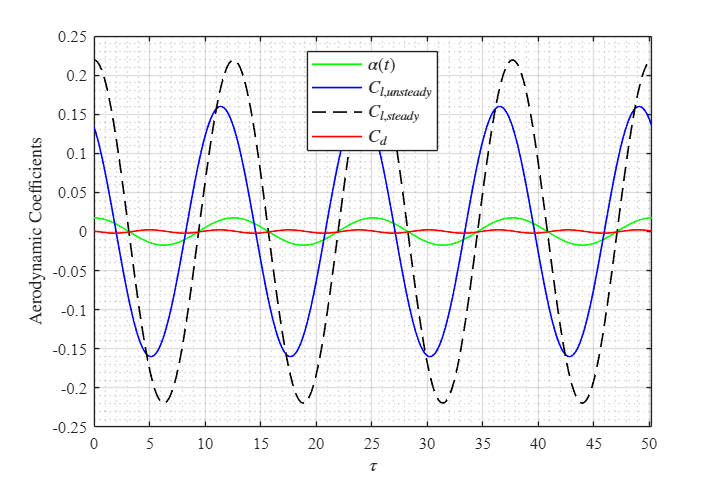

%% Unsteady Aerodynamic Forces Analysis

close all;
clc;
clear all;

% Parameters

a = -0.5; % Non dimensional distance between the rotation axis (Elastic Axis) and the geometrical center (x = 0) 
alpha = deg2rad(1); % Amplitude of AoA perturbation. 
k =  0.5; % Reduced frequency. Here is a parameter, in flutter solvers it's part of the solution itself
C = Theodorsen_function(k); % Calls Theodorsen function, and introduces the value of k (reduced freq.)

% Complex Unsteady Lift Amplitude from Theodorsen Model

C_l = 2*pi*(a*k^2 + 1i*k + 2*C*(1 + (1/2 - a)*1i*k))*alpha; 
C_l_amplitude = abs(C_l); % Amplitude of the Lift Coefficient 
C_l_phase = angle(C_l); % Phase angle with respect to the AoA motion

% Complex Steady Lift Amplitude (assuming instantaneous response, and no
% trailing edge unsteady vortex shedding)

C_l_steady = 4*pi*alpha;
C_l_steady_amplitude  = abs(C_l_steady);
C_l_steady_phase = angle(C_l_steady);

% Unsteady Drag, from Garrick's Model

C_d = 2*pi*(a*k^2 + 1i*k + 2*C*(1 + (1/2 - a)*1i*k))*alpha^2 - ...
    pi*(2*C*(1 + 1i*k*(1/2 - a)) - 1i*k)^2*alpha^2; % C_l*alpha - C_s
C_d_amplitude = abs(C_d); % Amplitude of the Lift Coefficient 
C_d_phase = angle(C_d); % Phase angle with respect to the AoA motion

% Circulatory and Non Circulatory Lift contributions. Just to study C_l
% behavior in more detail.

C_l_C = 2*pi*(2*C*(1 + (1/2 - a)*1i*k))*alpha; % Circulatory contribution
C_l_C_amplitude = abs(C_l_C); % Amplitude of the Lift Coefficient 
C_l_C_phase = angle(C_l_C); % Phase angle with respect to the AoA motion

C_l_NC = 2*pi*(a*k^2 + 1i*k)*alpha; % Non circulatory contribution
C_l_NC_amplitude = abs(C_l_NC); % Amplitude of the Lift Coefficient 
C_l_NC_phase = angle(C_l_NC); % Phase angle with respect to the AoA motion

% Aerodynamic forces in real Time Domain

n = 4; % Number of cycles to plot the response
tau_lim = 2*pi/k*n;
tau = linspace(0, tau_lim, 1000); % Time array 
alpha_t = alpha*cos(k*tau);
Cl_t = C_l_amplitude*cos(k*tau + C_l_phase);
Cl_t_steady = C_l_steady_amplitude*cos(k*tau + C_l_steady_phase);
Cd_t = C_d_amplitude*cos(2*k*tau + C_d_phase); % The 2 comes from the alpha^2;
Cl_C_t = C_l_C_amplitude*cos(k*tau + C_l_C_phase);
Cl_NC_t = C_l_NC_amplitude*cos(k*tau + C_l_NC_phase);

% Time Plots


figure(1)

plot(tau, alpha_t,'g','LineWidth',1);
hold on
plot(tau, Cl_t,'b','LineWidth',1);
hold on
plot(tau, Cl_t_steady,'black--','LineWidth',1);
hold on 
plot(tau, Cd_t,'r','LineWidth',1);
hold on 
legend('$\alpha(t)$','$C_{l,unsteady}$', '$C_{l,steady}$', '$C_d$','Interpreter', 'latex','FontSize', 11, 'Location', 'best');
xlabel('$\tau$','interpreter','latex')
ylabel('Aerodynamic Coefficients','interpreter','latex')
xlim([0 tau_lim])
grid on
grid minor
box on
set(gcf, 'Units', 'inches', 'Position', [0, 0, 6, 4]);
set(gca, 'FontSize', 10, 'FontName', 'Times New Roman')

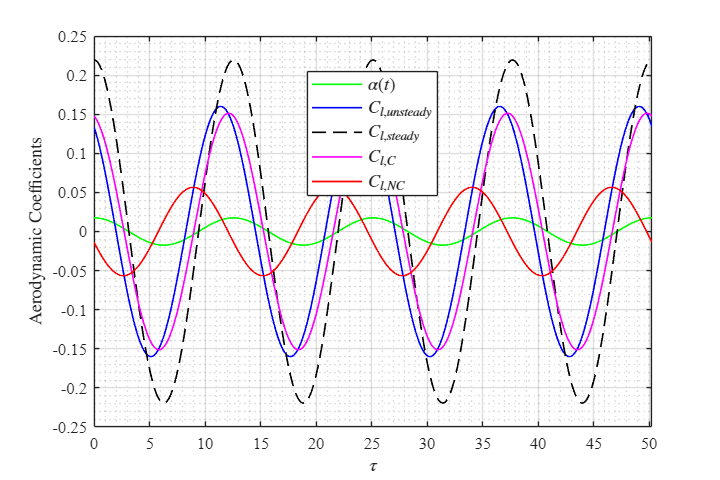


figure(2)

plot(tau, alpha_t,'g','LineWidth',1);
hold on
plot(tau, Cl_t,'b','LineWidth',1);
hold on
plot(tau, Cl_t_steady,'black--','LineWidth',1);
hold on 
plot(tau, Cl_C_t,'m','LineWidth',1);
hold on 
plot(tau, Cl_NC_t,'r','LineWidth',1);
legend('$\alpha(t)$','$C_{l,unsteady}$', '$C_{l,steady}$', '$C_{l,C}$','$C_{l,NC}$','Interpreter', 'latex','FontSize', 11, 'Location', 'best');
xlabel('$\tau$','interpreter','latex')
ylabel('Aerodynamic Coefficients','interpreter','latex')
xlim([0 tau_lim])
grid on
grid minor
box on
set(gcf, 'Units', 'inches', 'Position', [0, 0, 6, 4]);
set(gca, 'FontSize', 10, 'FontName', 'Times New Roman')

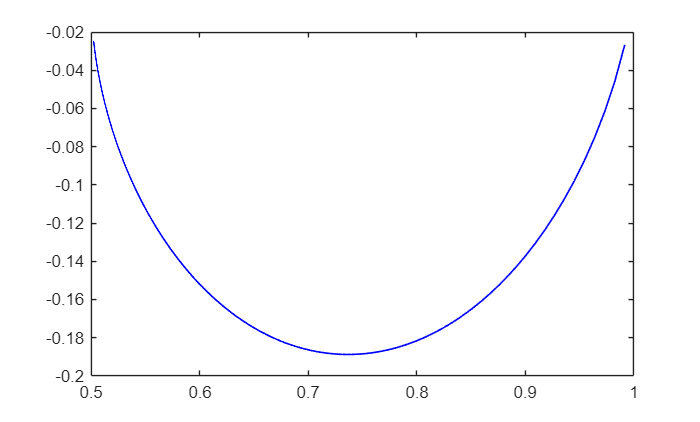



%% Theodorsen's Function Analysis

k_range = linspace(0,5,1000);
C_plot = zeros(1000,1);

for i = 1:1000
    C_plot(i) = Theodorsen_function(k_range((i)));
end

figure(3)
plot(real(C_plot), imag(C_plot),'b','LineWidth',1);

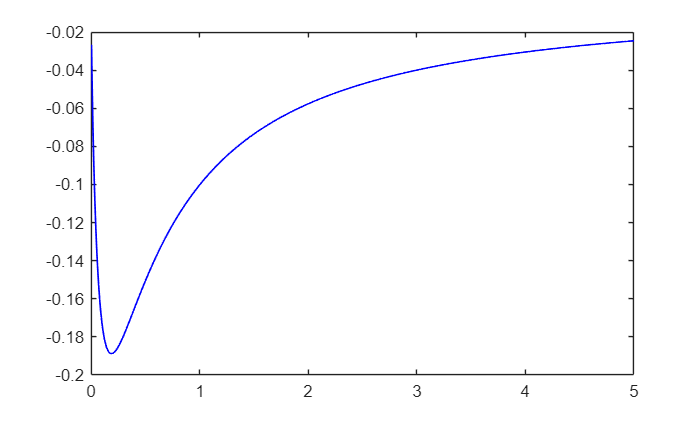


figure(4)
plot(k_range, imag(C_plot),'b','LineWidth',1);

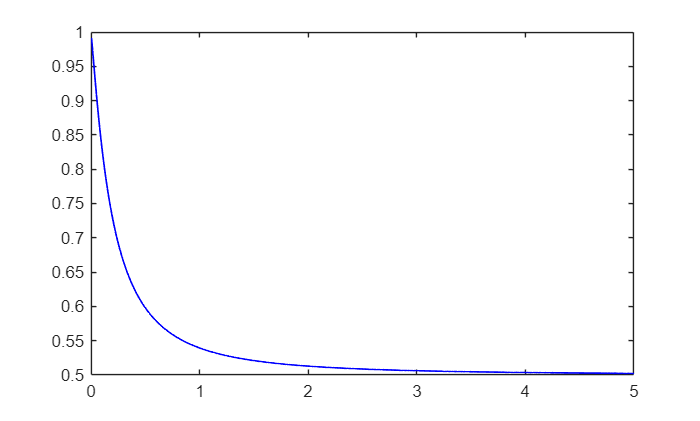


figure(5)
plot(k_range, real(C_plot),'b','LineWidth',1);

Typical values of the reduced frequency at which flutter in real wings occur is in the range of $0<k<1$. For these values, the plots tell us that the unsteady drag is extremely low in comparison with the unsteady lift. We can see that the values of the phase lag with respect to the pitching oscillations are similar, but the amplitude of the unsteady drag falls. 